# **Obtener los datos del archivo .csv**

data = readmatrix("../Data/150_120_CQRobot.csv");

t = data(:,1); %tiempo
u = data(:,2); %señal de referencia
y = data(:,3); %señal de salida

Ts = 0.0370;

# **Gráfica de la salida del sistema**

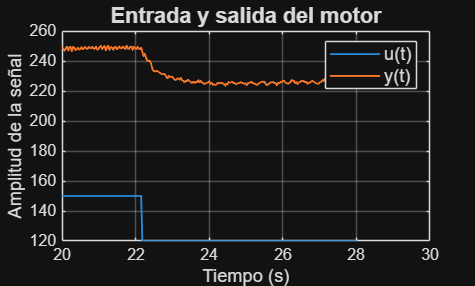

figure(1);
plot(t,u,t,y,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)', 'y(t)','FontSize',11);
title('Entrada y salida del motor', 'FontSize',13);
grid on;

# **Eliminar el DC Offset**


porcentaje_inicial = 0.10; % Se toma un aproximado de qué porcentaje de la respuesta 
num_puntos = length(y);
puntos_iniciales = round(porcentaje_inicial * num_puntos);
dc_offset_u = mean(u(1:puntos_iniciales));
dc_offset_y = mean(y(1:puntos_iniciales));

u_sindc = u - dc_offset_u;
y_sindc = y - dc_offset_y;

# **Gráfica de la salida sin el DC Offset**

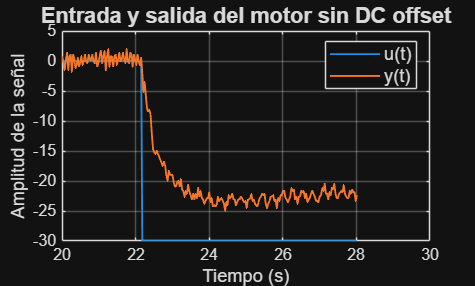

figure(2);
plot(t, u_sindc, t, y_sindc, 'LineWidth',1.1);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# **Abrir el System Identification Toolbox**

systemIdentification();

Se puede cargar el valor de la planta ya calculada con un 90.84% de precisión dándole click al modelo_primer_orden.mat

# Gráfica con del modelo de Toolbox

t1 = (20:0.0370:29)'

t1 =            20
       20.037
       20.074
       20.111
       20.148
       20.185
       20.222
       20.259
       20.296
       20.333
        20.37
       20.407
       20.444
       20.481
       20.518


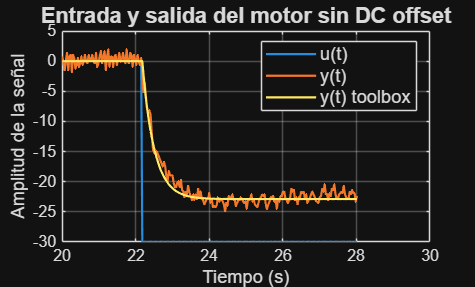

y_sim = lsim(P1D, u_sindc, t1);

figure(3);
plot(t, u_sindc, t, y_sindc, t, y_sim, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) toolbox', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Método de mínimos cuadrados

Y = y_sindc(3:end);
X = [y_sindc(2:end-1) y_sindc(1:end-2) u_sindc(2:end-1) u_sindc(1:end-2)];

cita = (X' * X) \ (X' * Y);

cita = round(cita,4); % se redondea el cita a 4 decimales
z = tf('z');
Hz = tf([cita(3) cita(4)], [1 -cita(1) -cita(2)], Ts); % se crea la función de transferencia
format shortG
Hz


Hz =
 
     0.1437 z - 0.0514
  -----------------------
  z^2 - 0.5008 z - 0.3763
 
Sample time: 0.037 seconds
Discrete-time transfer function.


# Gráfica con el método de mínimos cuadrados

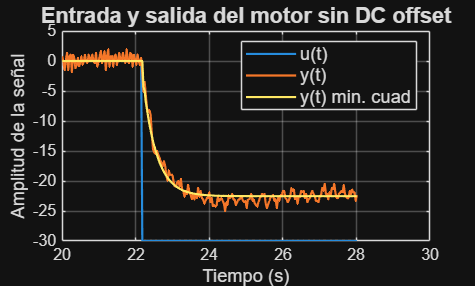

y_sim1 = lsim (Hz, u_sindc);

figure(4);
plot(t, u_sindc, t, y_sindc, t, y_sim1, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) min. cuad', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# ** Datos necesarios para el método de Alfaro**

porcentaje_final = 0.10; % Se toma un aproximado de donde la respuesta tiene su valor final
num_puntos = length(y);
puntos_final = round(porcentaje_final * num_puntos);
y_final = y_sindc(end-puntos_final+1:end);
promedio_yfinal = mean(y_final);

% Calcular y_inicial 
puntos_iniciales = round(0.10 * num_puntos);
y_inicial = mean(y_sindc(1:puntos_iniciales));

% Encontrar cambio_esc
cambio_esc = find(u_sindc < 0, 1);

deltau = u(1) - u(cambio_esc);

deltay = y_inicial - promedio_yfinal;

deltay25 = y_inicial - 0.25 * deltay;
deltay50 = y_inicial - 0.5 * deltay;
deltay75 = y_inicial - 0.75 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t25
todos_t25 = find(y_sindc(cambio_esc:end) <= deltay25);
pos_t25 = todos_t25(min(1, end)) + cambio_esc - 1;

% Para t50
todos_t50 = find(y_sindc(cambio_esc:end) <= deltay50);
pos_t50 = todos_t50(min(1, end)) + cambio_esc - 1;

% Para t75
todos_t75 = find(y_sindc(cambio_esc:end) <= deltay75);
pos_t75 = todos_t75(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t25_tot = t(pos_t25);
t50_tot = t(pos_t50);
t75_tot = t(pos_t75);
tcambio = t(cambio_esc);

% Se resta el tiempo antes de hacer el cambio escalón
t25 = t25_tot - tcambio;
t50 = t50_tot - tcambio;
t75 = t75_tot - tcambio;

# Método de PDMTM Alfaro (método de 2 puntos)

a = 0.5776

a =        0.5776


b = 1.5552

b =        1.5552


K = deltay / deltau;
T = a*(t75 - t25);
%No se calcula L ya que la planta no tiene tiempo muerto

# Gráfica con el método de Alfaro PDMTM

s = tf('s');
P1 = K / (T*s + 1)^2


P1 =
 
            0.7339
  --------------------------
  0.06116 s^2 + 0.4946 s + 1
 
Continuous-time transfer function.


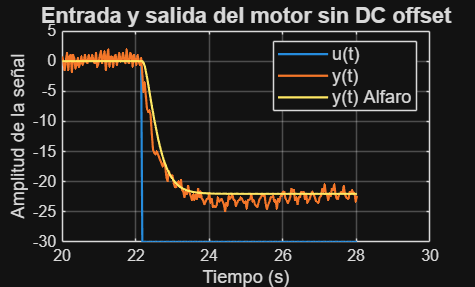

y_sim2 = lsim (P1, u_sindc, t1);
figure(5);

plot(t, u_sindc, t, y_sindc, t, y_sim2, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'y(t) Alfaro','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Cálculo de lo necesario para Ho

deltay35 = y_inicial - 0.35 * deltay;
deltay85 = y_inicial - 0.85 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t35
todos_t35 = find(y_sindc(cambio_esc:end) <= deltay35);
pos_t35 = todos_t35(min(1, end)) + cambio_esc - 1;

% Para t85
todos_t85 = find(y_sindc(cambio_esc:end) <= deltay85);
pos_t85 = todos_t85(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t35_tot = t(pos_t35);
t85_tot = t(pos_t85);

% Se resta el tiempo antes de hacer el cambio escalón
t35 = t35_tot - tcambio;
t85 = t85_tot - tcambio;

# Método de PDMTM Ho (método de 2 puntos)

aho = 0.463

aho =         0.463


K = deltay / deltau;
Tho = aho*(t85 - t35);

%No se calcula L ya que la planta no tiene tiempo muerto
P2 = K / (Tho*s + 1)^2


P2 =
 
            0.7339
  --------------------------
  0.05966 s^2 + 0.4885 s + 1
 
Continuous-time transfer function.


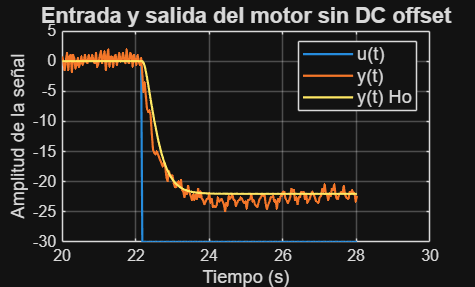

y_sim3 = lsim (P2, u_sindc, t1);

figure(6);
plot(t, u_sindc, t, y_sindc, t, y_sim3, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) Ho', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Método de alfaro 3 puntos

a3 = (-0.6240*t25 + 0.9866*t50 - 0.3626*t75)/(0.3533*t25 - 0.7036*t50 + 0.3503*t75);
T3 = (t75 - t25) / (0.9866+0.7036*a)

T3 =       0.30736


% No se calcula L ya que no tiene tiempo muerto

P3 = K/((T*s+1)*(a*T*s+1))


P3 =
 
            0.7339
  --------------------------
  0.03533 s^2 + 0.3901 s + 1
 
Continuous-time transfer function.


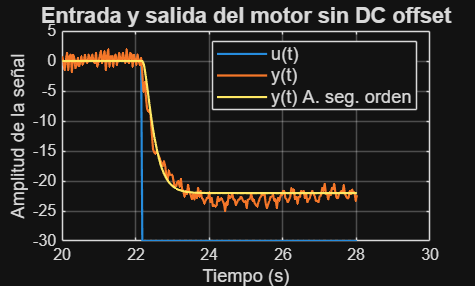

y_sim4 = lsim (P3, u_sindc, t1);

figure(7);
plot(t, u_sindc, t, y_sindc, t, y_sim4, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) A. seg. orden', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Comparación de las gráficas

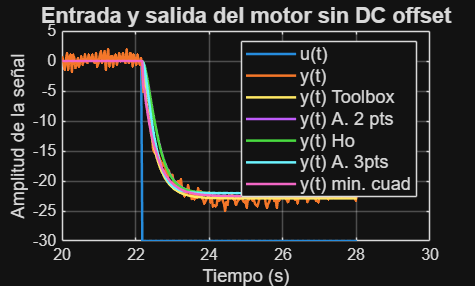

figure(8);
plot(t, u_sindc, t, y_sindc, t, y_sim, t, y_sim2, t, y_sim3, t, y_sim4,t, y_sim1,'LineWidth',1.5);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) Toolbox','y(t) A. 2 pts', 'y(t) Ho', 'y(t) A. 3pts', 'y(t) min. cuad','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Cálculos para elección de modelo de planta

%% Planta obtenida a través de toolbox
e_tbx = y_sindc - y_sim; % error de la planta de toolbox

IAE_tbx = sum(abs(e_tbx)) * Ts; % índice integral de error absoluto de la planta toolbox
ISE_tbx = sum(e_tbx.^2) * Ts; % índice de error cuadrático de la planta toolbox
ajuste_tbx = 100 * (1 - norm(e_tbx)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta toolbox

%% Planta obtenida a través de Alfaro 2 puntos
e_alfdos = y_sindc - y_sim2; % error de la planta de Alfaro 2 puntos

IAE_alfdos = sum(abs(e_alfdos)) * Ts; % índice integral de error absoluto de la planta de Alfaro 2 puntos
ISE_alfdos = sum(e_alfdos.^2) * Ts; % índice de error cuadrático de la planta Alfaro 2 puntos
ajuste_alfdos = 100 * (1 - norm(e_alfdos)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Alfaro 2 puntos


%% Planta obtenida a través de Ho 2 puntos
e_hodos = y_sindc - y_sim3; % error de la planta de Ho 2 puntos

IAE_hodos = sum(abs(e_hodos)) * Ts; % índice integral de error absoluto de la planta de Ho 2 puntos
ISE_hodos = sum(e_hodos.^2) * Ts; % índice de error cuadrático de la planta Ho 2 puntos
ajuste_hodos = 100 * (1 - norm(e_hodos)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Ho 2 puntos

%% Planta obtenida a través de Alfaro 3 puntos
e_alftres = y_sindc - y_sim4; % error de la planta de Alfaro 3 puntos

IAE_alftres = sum(abs(e_alftres)) * Ts; % índice integral de error absoluto de la planta de Alfaro 3 puntos
ISE_alftres = sum(e_alftres.^2) * Ts; % índice de error cuadrático de la planta Alfaro 3 puntos
ajuste_alftres = 100 * (1 - norm(e_alftres)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Alfaro 3 puntos

# Datos relevantes y elección de planta

IAE_vec = [IAE_tbx, IAE_alfdos, IAE_hodos, IAE_alftres];
ISE_vec = [ISE_tbx, ISE_alfdos, ISE_hodos, ISE_alftres];
ajuste_vec = [ajuste_tbx, ajuste_alfdos, ajuste_hodos, ajuste_alftres];
nombres = {'Toolbox', 'Alfaro 2p', 'Ho 2p', 'Alfaro 3p'};

[~, mejor_IAE] = min(IAE_vec);
[~, mejor_ISE] = min(ISE_vec);
[~, mejor_ajuste] = max(ajuste_vec);

%% Resultados
fprintf('Mejor IAE: %s (%.4f)\n', nombres{mejor_IAE}, IAE_vec(mejor_IAE));

Mejor IAE: Toolbox (7.2760)


fprintf('Mejor ISE: %s (%.4f)\n', nombres{mejor_ISE}, ISE_vec(mejor_ISE));

Mejor ISE: Toolbox (9.1924)


fprintf('Mejor Ajuste: %s (%.4f%%)\n', nombres{mejor_ajuste}, ajuste_vec(mejor_ajuste));

Mejor Ajuste: Toolbox (90.0230%)


# Datos de planta P1D

%Constante tau0 de la planta
tau0 = P1D.Td/P1D.Tp1

tau0 =      0


# Cálculo controlador PI con Método Ziegler y Nichols para P1D

%Cálculo parámetros del controlador
kpzn = (0.31+ 1.28*tau0)/P1D.Kp;
tizn = ((3.34+1.28*tau0)/(1+0.787*tau0))*P1D.Tp1*tau0;

%Controlador C1 con método Ziegler y Nichols
C1 = kpzn/(tizn*s + 1)


C1 =
 
  0.4061
 
Static gain.


# Gráfica salida con Controlador #1

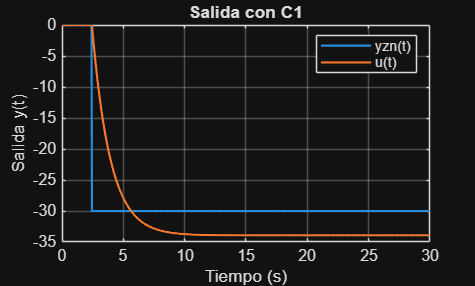

%Entradas y tiempos de simulación
t_sim = (0:(t1(2) - t1(1)):30)';
u_sim =(-30 * ( (1:811) >= 67 & (1:811) < 67+811 ))';

%Cálculo de salida del sistema ante cambios en perturbación
Mydsn = (P1D.Kp/(P1D.Tp1 *s + 1))/(1 + C1 *(P1D.Kp/(P1D.Tp1 * s + 1)));
ysimzn = lsim(Mydzn,u_sim,t_sim);

%Gráfica de salida del sistema ante cambios en perturbación
plot(t_sim,u_sim,t_sim,ysimzn,'LineWidth',1.3);

%Detalles gráfica
title('Salida con C1');
xlabel('Tiempo (s)');
ylabel('Salida y(t)');
legend ('yzn(t)', 'u(t)');
grid on;

# Cálculo controlador PI con Síntesis Analítica para P1D

%Cálculo tauc de acuerdo a Doc Emerson
tauc = 3 * P1D.Tp1

tauc =        1.0947


%Cálculo parámetros del controlador
ksn = (2- tauc)/(tauc * P1D.Kp);
tisn = tauc * P1D.Tp1 * (2 - tauc);

%Controlador C2 con método síntesis analítica
C2 = ksn/(s * (tisn * s + 1))


C2 =
 
      1.083
  --------------
  0.3616 s^2 + s
 
Continuous-time transfer function.


# Gráfica salida con Controlador #2

%Entradas y tiempos de simulación
t_sim = (0:(t1(2) - t1(1)):30)';
u_sim =(-30 * ( (1:811) >= 67 & (1:811) < 67+811 ))';

%Cálculo de salida del sistema ante cambios en perturbación
Mydsn = (P1D.Kp/(P1D.Tp1 *s + 1))/(1 + C2 *(P1D.Kp/(P1D.Tp1 * s + 1)));


Mydsn =
 
           0.1007 s^3 + 0.5546 s^2 + 0.7634 s
  -----------------------------------------------------
  0.04815 s^4 + 0.397 s^3 + 1.091 s^2 + 1.302 s + 0.827
 
Continuous-time transfer function.


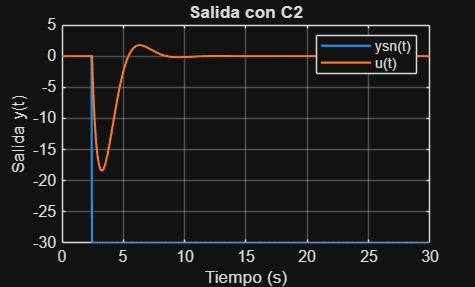

ysimsn = lsim(Mydsn,u_sim,t_sim);

%Gráfica de salida del sistema ante cambios en perturbación
plot(t_sim,u_sim,t_sim,ysimsn,'LineWidth',1.3);

%Detalles gráfica
title('Salida con C2');
xlabel('Tiempo (s)');
ylabel('Salida y(t)');
legend ('ysn(t)', 'u(t)');
grid on;